#### Víctor Asanza, Rebeca Estrada, Danny Torres, Steven Santillan and Juan Cadena

- `Main Code: `[https://github.com/vasanza/Matlab_Code/tree/Weather-Monitoring-Station](https://github.com/vasanza/Matlab_Code/tree/Weather-Monitoring-Station)

- `DataPort: `[https://dx.doi.org/10.21227/mdfs-ya42](https://dx.doi.org/10.21227/mdfs-ya42)

- `More Matlab Examples: `[https://github.com/vasanza/Matlab_Code](https://github.com/vasanza/Matlab_Code)

- `Read more: `[https://vasanza.blogspot.com/](https://vasanza.blogspot.com/)

# Initialization

clear;clc;
path = fullfile('./Data/agriculture.mat');
Datos=load(path);Datos=Datos.Datos;
nDatos=(Datos./max(Datos));

addpath(genpath('./src'))%functions folders
% inputs: Item, air humidity, air temperature, soil moisture, light and rain
input=nDatos(1:length(nDatos)-1,2:6);
% output: soil moisture in the following time step
output=nDatos(2:length(nDatos),4);

# Data Visualization

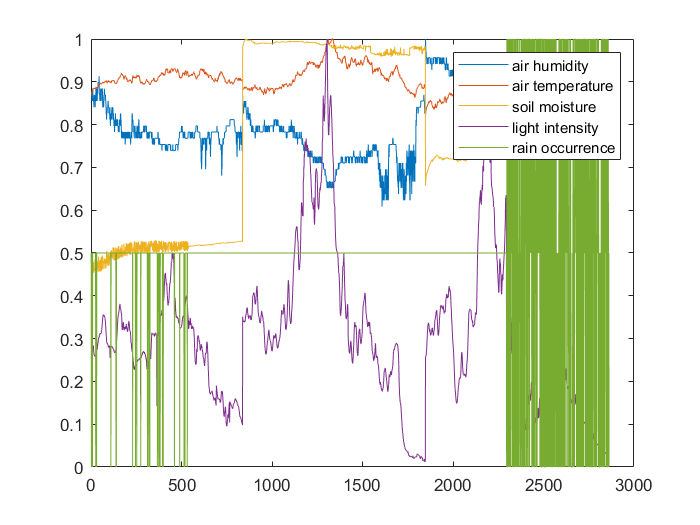

plot(input)
legend('air humidity', 'air temperature', 'soil moisture', 'light intensity', 'rain occurrence');

# Training with 70% Dataset

output70=[];yest70=[];
output70=output(1:round(length(output)*.7));
input70=input(1:round(length(input)*.7),:);
nnstart

# Testing NN as Regression (Bayesian Regularization)

yest = myNeuralNetworkFunction_BR(input70)

yest =     0.4653
    0.4562
    0.4569
    0.4767
    0.4592
    0.4677
    0.4686
    0.4598
    0.4723
    0.4677


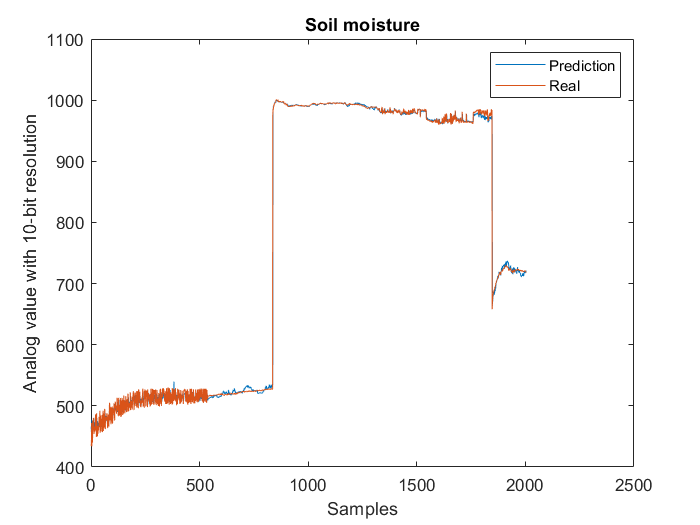

figure
plot(yest*max(Datos(:,4)))
hold on
plot(output70*max(Datos(:,4)))
title("Soil moisture");legend("Prediction","Real");
xlabel("Samples");ylabel("Analog value with 10-bit resolution");

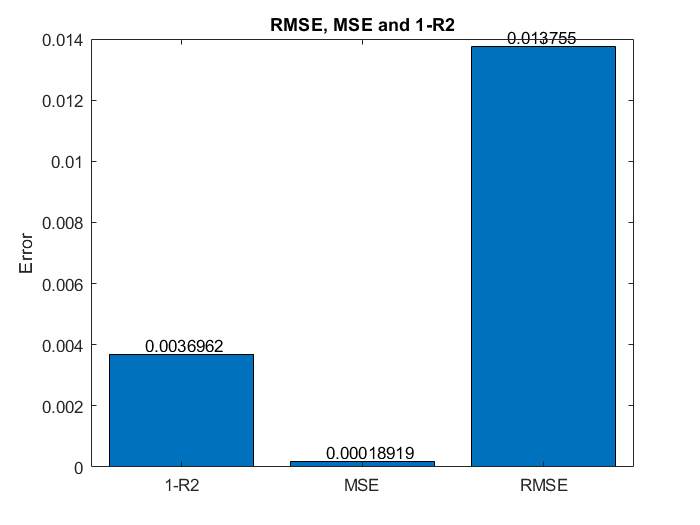

rmse = 0.0138

mse = 1.8919e-04

r2 = 0.9963


[rmse,mse,r2] = fBar_RmseMseR2(yest,output70)

# Testing NN as Regression (Levenberg-Marquardt)

yest = myNeuralNetworkFunction_LM(input70)

yest =     0.4561
    0.4599
    0.4456
    0.4736
    0.4549
    0.4620
    0.4654
    0.4656
    0.4658
    0.4609


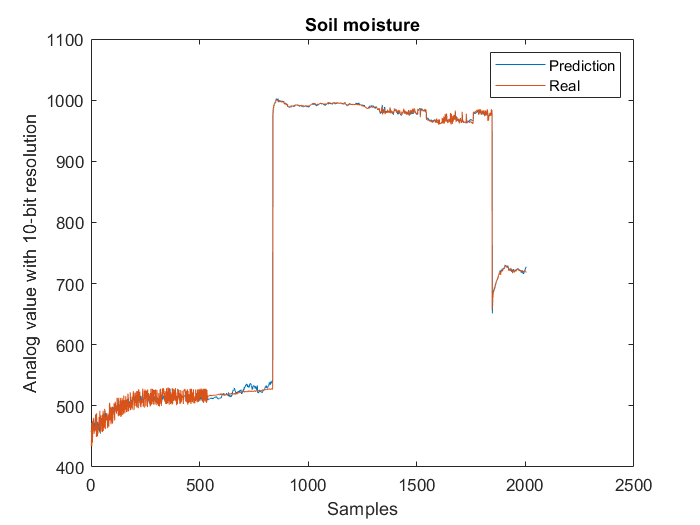

figure
plot(yest*max(Datos(:,4)))
hold on
plot(output70*max(Datos(:,4)))
title("Soil moisture");legend("Prediction","Real");
xlabel("Samples");ylabel("Analog value with 10-bit resolution");

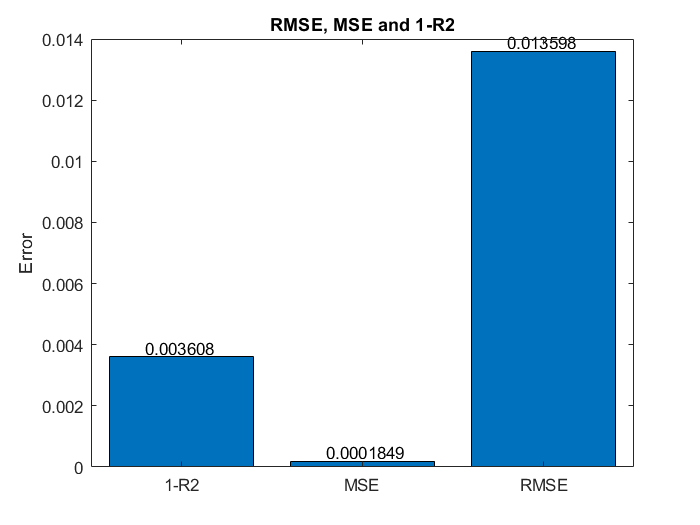

rmse = 0.0136

mse = 1.8490e-04

r2 = 0.9964


[rmse,mse,r2] = fBar_RmseMseR2(yest,output70)

# Testing NN as Regression (Bayesian Regularization) - with 30% Dataset

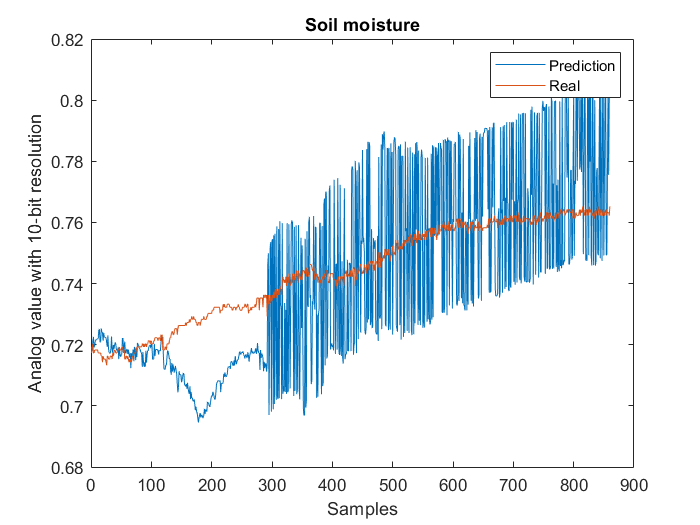

output30=[];yest30=[];input30=[];
output30=output(round(length(output)*.7):length(output));
input30=input(round(length(input)*.7):length(input),:);
yest30=myNeuralNetworkFunction_BR(input30);
yest=myNeuralNetworkFunction_BR(input);

figure
plot(yest30)
hold on
plot(output30)
title("Soil moisture");legend("Prediction","Real");
xlabel("Samples");ylabel("Analog value with 10-bit resolution");

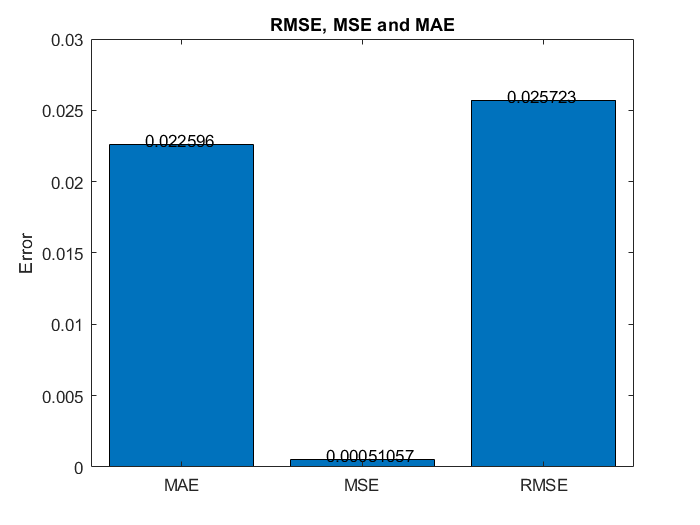

rmse = 0.0226

mse = 5.1057e-04

mae = 0.0257

[rmse,mse,mae] = fBar_RmseMseMae(yest30,output30)

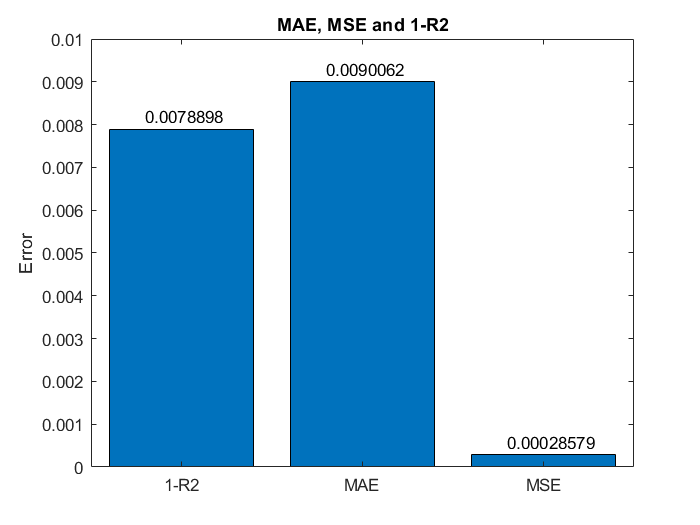

mae = 0.0090

mse = 2.8579e-04

r2 = 0.9921

[mae,mse,r2] = fBar_MaeMseR2(yest,output)